# Derivation of state equation for thermal network

close all;
clear;
clc;

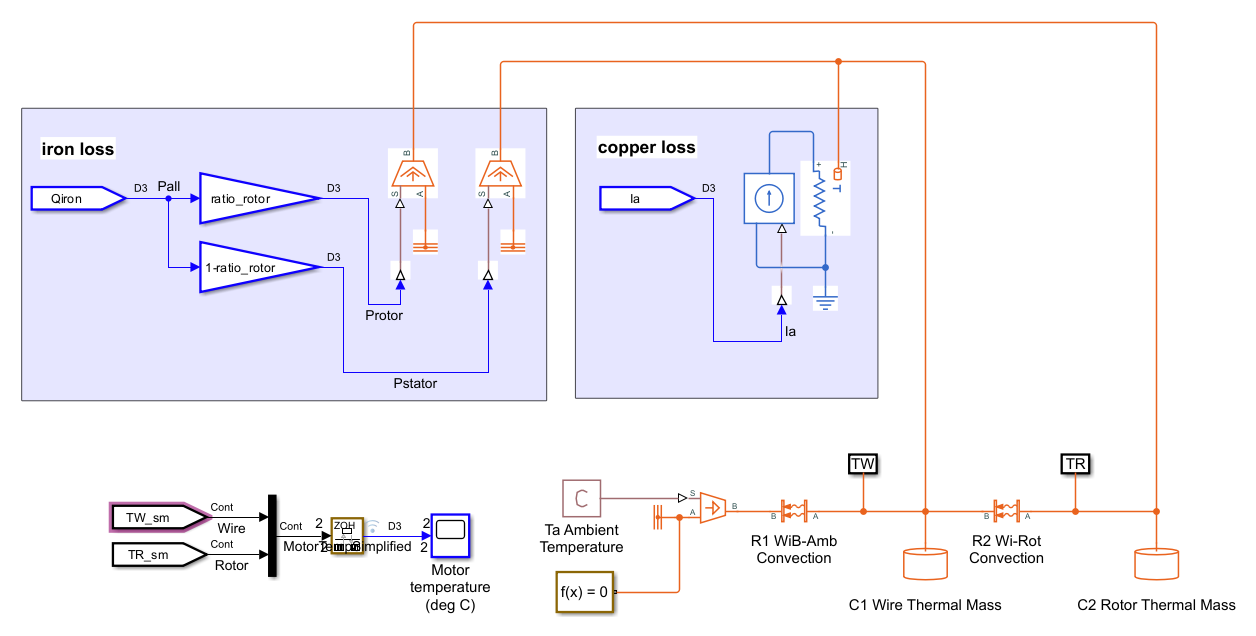

## define variables

### state

$x_1$ wire temperature $T_W \mathrm{[K]}$

$x_2$ rotor temperature $T_R \mathrm{[K]}$

### input

$u_1$ armature current $I_a \mathrm{[A]}$

$u_2$ ambient temperature $T_a \mathrm{[K]}$

$u_3$ iron loss $Q_{iron} \mathrm{[W]}$

% states
syms x [2,1] real
T_W = x(1);
T_R = x(2);

% inputs
syms u [3,1] real
I_a = u(1);
T_a = u(2);
Q_iron = u(3);

% params
syms R [2,1] real
syms C [2,1] real
syms T_0 real
syms R_0 real
syms alpha real
syms ratio_rotor real

## heat flux

### copper loss

Q_copper = I_a^2*R_0*(1+alpha*(T_W-T_0));

### iron loss

Q_iron_wire = Q_iron*(1-ratio_rotor);
Q_iron_rotor = Q_iron*ratio_rotor;

### through thermal resistance

q(1) = (T_W-T_a)/R(1);
q(2) = (T_R-T_W)/R(2);

## time derivative of temperature

#### state equation

f(1) = (Q_copper+Q_iron_wire-q(1)+q(2))/C(1);
f(2) = (Q_iron_rotor-q(2))/C(2);

f = f.'

$$f = \left(\begin{array}{c} -\frac{u_{3}\,\left({\mathrm{ratio}}_{\mathrm{rotor}}-1\right)-\frac{u_{2}-x_{1}}{R_{1}}+\frac{x_{1}-x_{2}}{R_{2}}+R_{0}\,{u_{1}}^{2}\,\left(\alpha \,\left(T_{0}-x_{1}\right)-1\right)}{C_{1}}\\ \frac{{\mathrm{ratio}}_{\mathrm{rotor}}\,u_{3}+\frac{x_{1}-x_{2}}{R_{2}}}{C_{2}} \end{array}\right)$$

#### output equation

h(1) = T_R;

h = h.'

$$h = x_{2}$$

## substitute parameters

controller_parameters();
f = subs(f,C,C_);
f = subs(f,R,R_);
f = subs(f,[T_0,R_0,alpha], [T_0_,R_0_,alpha_]);
f = subs(f,ratio_rotor,ratio_rotor_);
f

$$f = \left(\begin{array}{c} \frac{u_{2}}{50}+\frac{u_{3}}{1200}-\frac{3\,x_{1}}{50}+\frac{x_{2}}{25}+\frac{13\,{u_{1}}^{2}\,\left(\frac{393\,x_{1}}{100000}-\frac{343459}{2000000}\right)}{300000}\\ \frac{3\,u_{3}}{800}+\frac{3\,x_{1}}{50}-\frac{3\,x_{2}}{50} \end{array}\right)$$

### export to file

matlabFunction(f,'File','nonlinear_model/state_equation.m','Vars',{x,u});
matlabFunction(h,'File','nonlinear_model/output_equation.m','Vars',{x});
matlabFunction(x+f*Ts,'File','nonlinear_model/state_equation_discrete.m','Vars',{x,u});

## linearization

### Jacobi matrix

A = jacobian(f,x)

$$A = \left(\begin{array}{cc} \frac{1703\,{u_{1}}^{2}}{10000000000}-\frac{3}{50} & \frac{1}{25}\\ \frac{3}{50} & -\frac{3}{50} \end{array}\right)$$

B = jacobian(f,u)

$$B = \left(\begin{array}{ccc} \frac{13\,u_{1}\,\left(\frac{393\,x_{1}}{100000}-\frac{343459}{2000000}\right)}{150000} & \frac{1}{50} & \frac{1}{1200}\\ 0 & 0 & \frac{3}{800} \end{array}\right)$$

C = jacobian(h,x)

$$C = \left(\begin{array}{cc} 0 & 1 \end{array}\right)$$

matlabFunction(A,'File','Jacobian/dfdx.m','Vars',{x,u});
matlabFunction(C,'File','Jacobian/dhdx.m','Vars',{x});

### equilibrium point

xe = [298.15,298.15]';
ue = [1.0,300,0.0]';

A_lin = double(subs(A,[x;u],[xe;ue]));
B_lin = double(subs(B,[x;u],[xe;ue]));
C_lin = double(subs(C,[x;u],[xe;ue]));

### observability

Go = obsv(A_lin,C_lin);
rank(Go)

ans = 2